
% 1. 提取数值数据为向量
x_data = lambda.Var1;  % 使用点运算符提取 x 的数据（作为横坐标）

无法解析名称 'lambda.Var1'。

y_data = light.Var2;   % 使用点运算符提取 y 的数据（作为纵坐标）
%data_he = light_he.Var2;

% 2. 绘制图形
figure; % 打开一个新的绘图窗口
plot(x_data, y_data, 'k', 'MarkerSize', 3, 'LineWidth', 1);
hold on;

% 修正后的轴标签（通常没问题，但如果仍然警告，可能也需要检查空格）
xlabel('$length$(nm)', 'Interpreter', 'latex'); 
ylabel('$I_{rel}$ ', 'Interpreter', 'latex');
xlim([400,660])
% 4. 添加网格线
grid off;

% 5. 设置图表细节（可选）
set(gca, 'FontSize', 12);


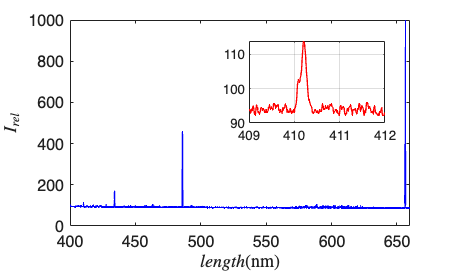

% 假设你的数据已经准备好了：
x_data = lambda.Var1;
y_data = light.Var2;

% 1. 绘制主图
figure;
plot(x_data, y_data, 'b', 'MarkerSize', 3, 'LineWidth', 1);
hold on;
xlabel('$length$(nm)', 'Interpreter', 'latex');
ylabel('$I_{rel}$', 'Interpreter', 'latex');
xlim([400,660])
grid off;
set(gca, 'FontSize', 12);

% 2. 添加放大图（Inset）
% 定义放大图的位置和大小 [left bottom width height]，取值0-1，相对于figure
inset_position = [0.55 0.55 0.3 0.3];  % 可以调节
axes('Position', inset_position);

% 绘制放大部分
idx = x_data >= 409 & x_data <= 412;  % 选取 x 在 409-412 的数据
plot(x_data(idx), y_data(idx), 'r', 'MarkerSize', 3, 'LineWidth', 1);
xlim([409,412])
grid on;
set(gca, 'FontSize', 10);

% 可选：放大图加边框
box on; % 从矩形指向 inset